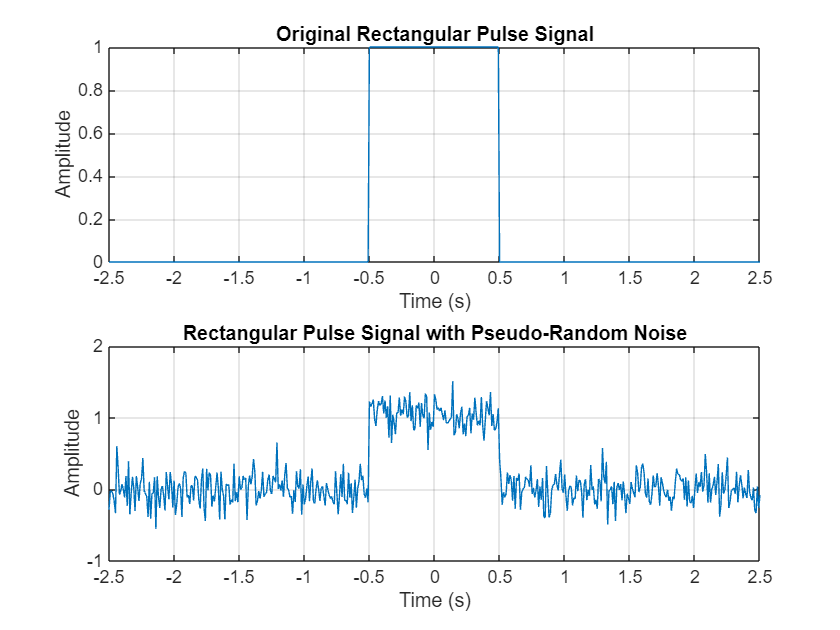

%% Parameters for the Rectangular Pulse
% Define the parameters for generating a rectangular pulse signal.

pulseWidth = 1;        % Width of the pulse (in seconds)
pulseAmplitude = 1;    % Amplitude of the pulse
samplingRate = 100;    % Sampling rate (in Hz)     ...should be 48 KHz
duration = 5;          % Duration of the signal (in seconds)

%% Time Vector
% Create a time vector centered around zero.

t = -duration/2 : 1/samplingRate : duration/2;

%% Generate the Rectangular Pulse Signal
% Use the `rectpuls` function to generate a rectangular pulse signal.

pulseSignal = pulseAmplitude * rectpuls(t, pulseWidth);

%% Generate Pseudo-Random Noise
% Generate pseudo-random noise to be added to the pulse signal.

noiseAmplitude = 0.2;    % Amplitude of the noise
noise = noiseAmplitude * randn(size(t));

%% Add Noise to the Pulse Signal
% Combine the rectangular pulse signal with the generated noise.

noisyPulseSignal = pulseSignal + noise;

%% Plot the Original Pulse Signal
% Plot the original rectangular pulse signal.

figure;
subplot(2,1,1); % Create a subplot (2 rows, 1 column, 1st plot)
plot(t, pulseSignal);
xlabel('Time (s)');
ylabel('Amplitude');
title('Original Rectangular Pulse Signal');
grid on;

%% Plot the Noisy Pulse Signal
% Plot the rectangular pulse signal with the added pseudo-random noise.

subplot(2,1,2); % Create a subplot (2 rows, 1 column, 2nd plot)
plot(t, noisyPulseSignal);
xlabel('Time (s)');
ylabel('Amplitude');
title('Rectangular Pulse Signal with Pseudo-Random Noise');
grid on;

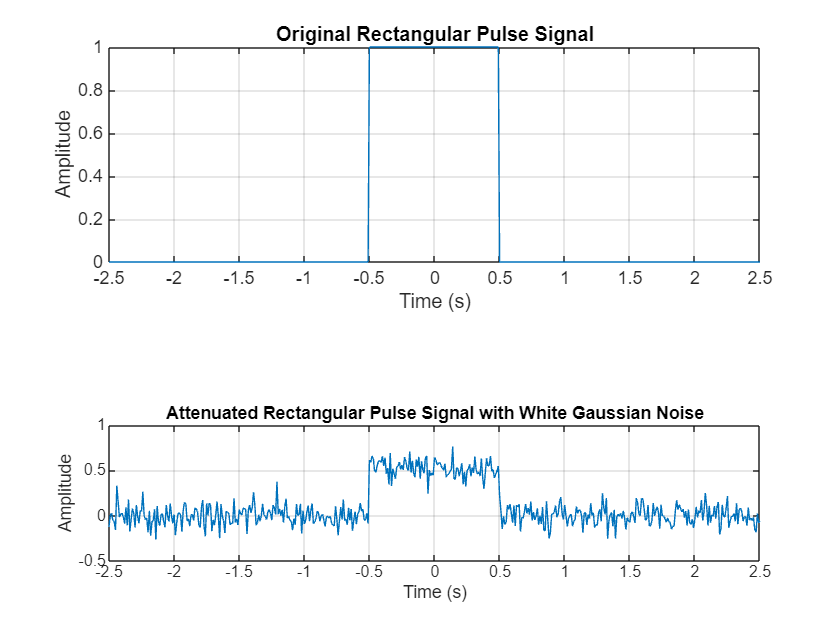


%% Introduce Attenuation Factor
% Define and apply an attenuation factor to the noisy pulse signal.

attenuationFactor = 0.5;    % Attenuation factor
attenuatedSignal = attenuationFactor * noisyPulseSignal;

%% Add White Gaussian Noise
% Add white Gaussian noise to the attenuated signal.

SNR = 20;  % Desired Signal-to-Noise Ratio in dB
signalPower = var(attenuatedSignal);  % Power of the signal
noisePower = signalPower / (10^(SNR/10));  % Calculate the noise power based on SNR
whiteNoise = sqrt(noisePower) * randn(size(t));  % Generate white Gaussian noise
attenuatedNoisySignal = attenuatedSignal + whiteNoise;


%% Plot the Attenuated and Noisy Pulse Signal
% Plot the attenuated rectangular pulse signal with white Gaussian noise.

subplot(3,1,3); % Create a subplot (3 rows, 1 column, 3rd plot)
plot(t, attenuatedNoisySignal);
xlabel('Time (s)');
ylabel('Amplitude');
title('Attenuated Rectangular Pulse Signal with White Gaussian Noise');
grid on;

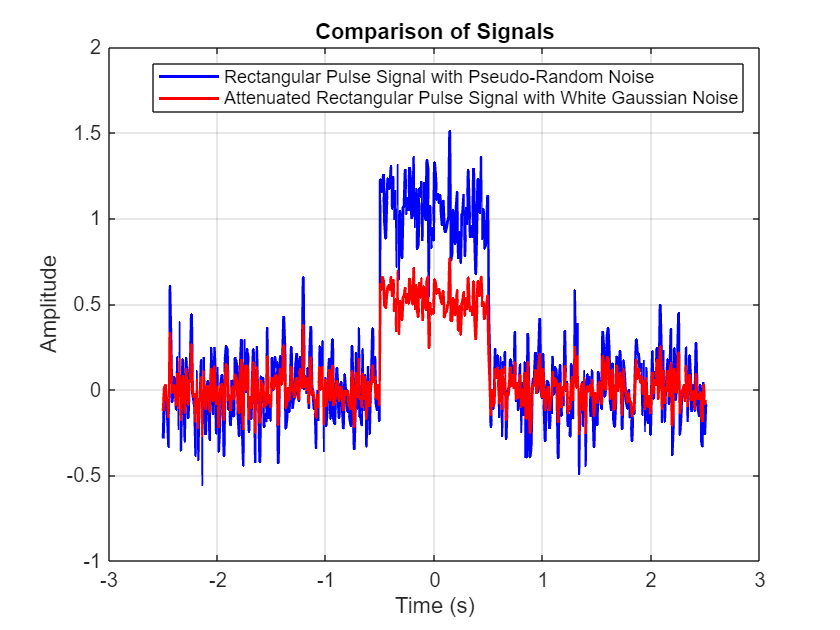

% Plot both signals on the same plot
figure;
plot(t, noisyPulseSignal, 'b', 'LineWidth', 1.5);  % Plot the noisy pulse signal in blue
hold on;  % Hold the current plot
plot(t, attenuatedNoisySignal, 'r', 'LineWidth', 1.5);  % Plot the attenuated and noisy pulse signal in red
hold off;  % Release the hold
xlabel('Time (s)');
ylabel('Amplitude');
title('Comparison of Signals');
legend('Rectangular Pulse Signal with Pseudo-Random Noise', 'Attenuated Rectangular Pulse Signal with White Gaussian Noise');
grid on;

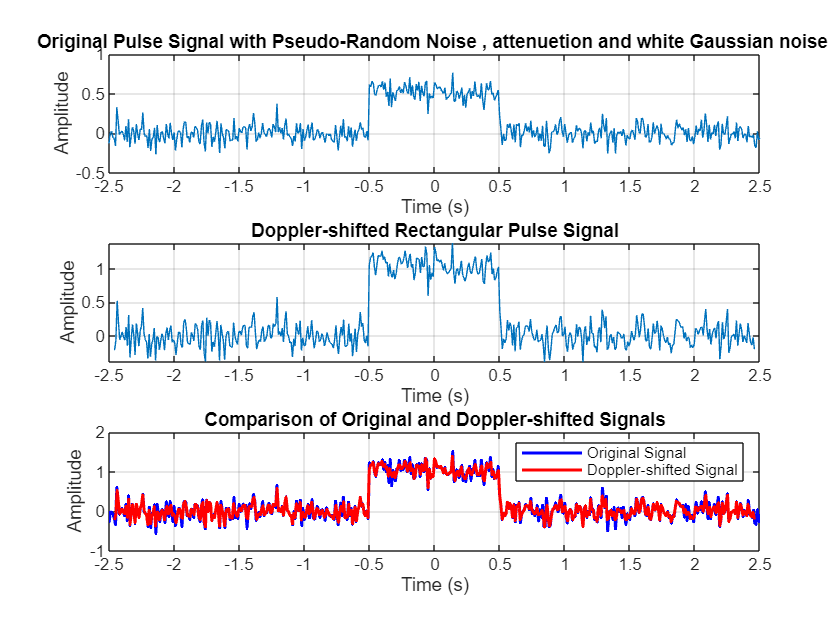

% Red is the plot which is denoted by (" X ") in the paper .

% Now to we have to introduce Doppler shift to this pulse 

% Parameters
sourceSpeed = 6;  % Speed of the source in m/s
speedOfSound = 343;  % Speed of sound in m/s

% Calculate Doppler shift factor
dopplerShiftFactor = 1 + sourceSpeed / speedOfSound;

% Calculate Doppler-shifted time vector
tDoppler = t / dopplerShiftFactor;

% Interpolate the signal to account for the Doppler shift
noisyPulseSignalDoppler = interp1(t, noisyPulseSignal, tDoppler, 'linear', 'extrap');

% Plot the original and Doppler-shifted signals in separate subplots
figure;
subplot(3,1,1);
plot(t, attenuatedNoisySignal);
xlabel('Time (s)');
ylabel('Amplitude');
title('Original Pulse Signal with Pseudo-Random Noise , attenuetion and white Gaussian noise ');
grid on;

subplot(3,1,2);
plot(tDoppler, noisyPulseSignalDoppler);
xlabel('Time (s)');
ylabel('Amplitude');
title('Doppler-shifted Rectangular Pulse Signal');
grid on;

% Plot the original and Doppler-shifted signals on the same plot for comparison
subplot(3,1,3);
plot(t, noisyPulseSignal, 'b', 'LineWidth', 1.5);  % Original signal in blue
hold on;
plot(tDoppler, noisyPulseSignalDoppler, 'r', 'LineWidth', 1.5);  % Doppler-shifted signal in red
hold off;
xlabel('Time (s)');
ylabel('Amplitude');
title('Comparison of Original and Doppler-shifted Signals');
legend('Original Signal', 'Doppler-shifted Signal');
grid on;

% Matched filter tree should be applied
% well as we have taken only one pulse as the dont need to make segments



